# Opgaver

## 3.11

clear all

fs = 48000;
fc_lo = 1200;
fc_hi = 3600;
M = 500;

f_res = fs / M

f_res = 96


fc_lo_bin = round(fc_lo / f_res)

fc_lo_bin = 13

fc_hi_bin = round(fc_hi / f_res)

fc_hi_bin = 38

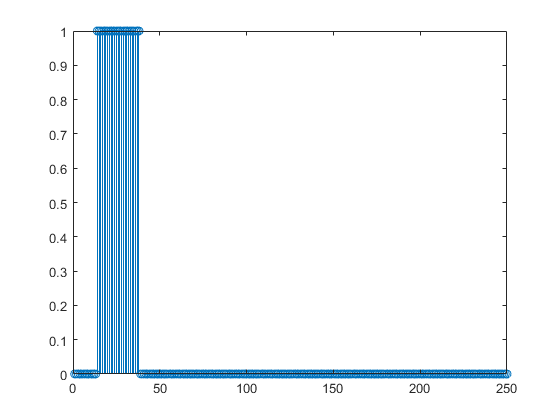


H = [zeros([1, fc_lo_bin]) ones([1, fc_hi_bin-fc_lo_bin]) zeros([1, M/2-fc_hi_bin])];
stem(H)

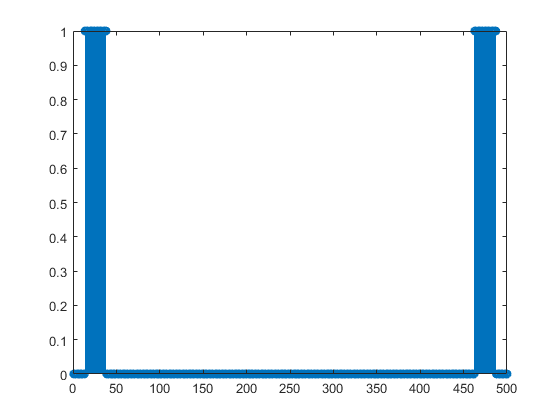


H = [H fliplr(H)];
stem(H)

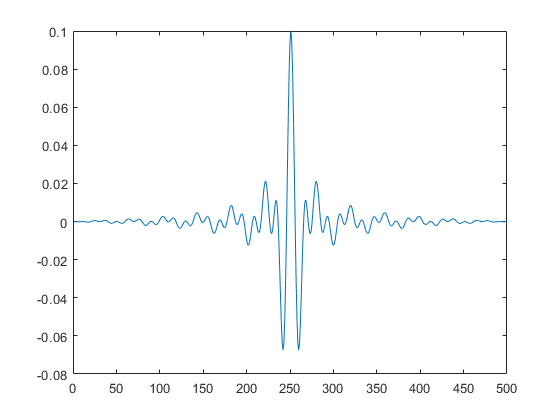


h = fftshift(real(ifft(H)));
plot(h)

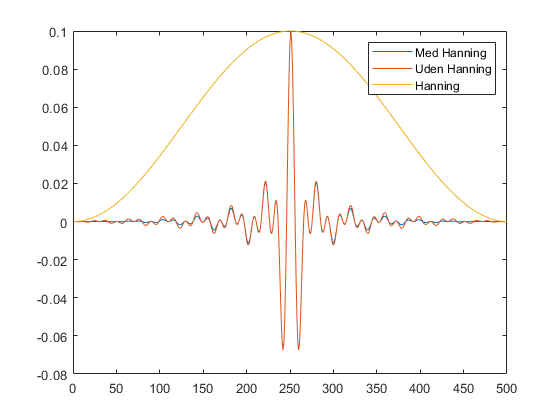


hanning_w = hanning(length(h))';
h_win = h .* hanning_w;

plot(h_win)
hold on
plot(h)
plot(hanning_w * max(h))
legend(["Med Hanning" "Uden Hanning" "Hanning"])
hold off

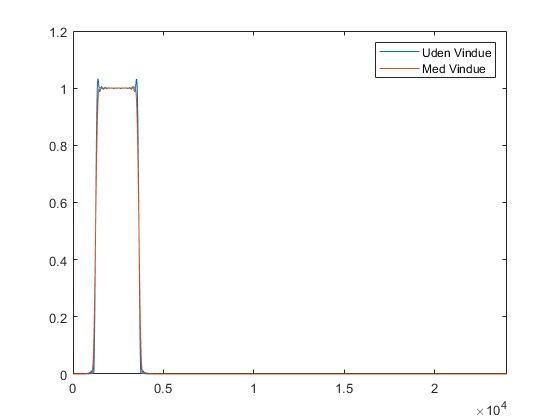


N_fft = fs;
f_vek = (0:N_fft-1) * fs / N_fft;

plot(f_vek, abs(fft(h, N_fft)))
xlim([0 fs/2])
hold on
plot(f_vek, abs(fft(h_win, N_fft)))
legend(["Uden Vindue" "Med Vindue"])
hold off

## 3.12

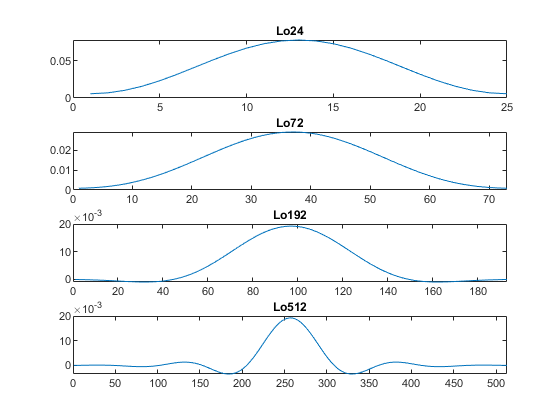

clear
close

fs = 44100;
fc = 850;

lo24 = fir1(24, fc/fs, "low");
lo72 = fir1(72, fc/fs, "low");
lo192 = fir1(192, fc/fs, "low");
lo512 = fir1(512, fc/fs, "low");

hi24 = fir1(24, fc/fs, "high");
hi72 = fir1(72, fc/fs, "high");
hi192 = fir1(192, fc/fs, "high");
hi512 = fir1(512, fc/fs, "high");

figure()
subplot(4,1,1)
plot(lo24)
xlim([0 length(lo24)])
title("Lo24")
subplot(4,1,2)
plot(lo72)
title("Lo72")
xlim([0 length(lo72)])
subplot(4,1,3)
plot(lo192)
title("Lo192")
xlim([0 length(lo192)])
subplot(4,1,4)
plot(lo512)
title("Lo512")
xlim([0 length(lo512)])

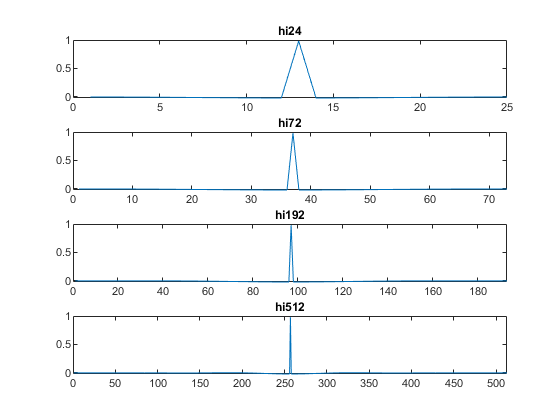


figure()
subplot(4,1,1)
plot(hi24)
xlim([0 length(hi24)])
title("hi24")
subplot(4,1,2)
plot(hi72)
title("hi72")
xlim([0 length(hi72)])
subplot(4,1,3)
plot(hi192)
title("hi192")
xlim([0 length(hi192)])
subplot(4,1,4)
plot(hi512)
title("hi512")
xlim([0 length(hi512)])

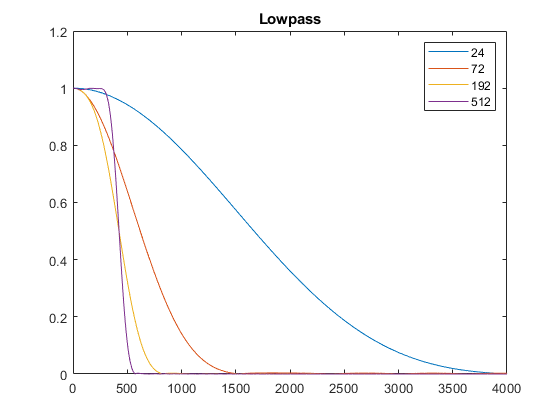


figure()
plot(0:fs-1, abs(fft(lo24, fs)))
xlim([0 4000])
title("Lowpass")
hold on
plot(0:fs-1, abs(fft(lo72, fs)))
plot(0:fs-1, abs(fft(lo192, fs)))
plot(0:fs-1, abs(fft(lo512, fs)))
legend(["24" "72" "192" "512"])
hold off

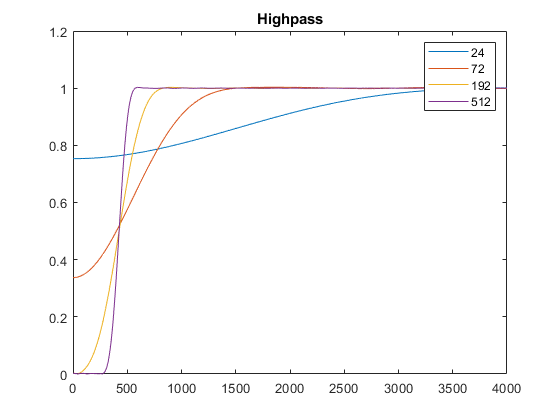


figure()
plot(0:fs-1, abs(fft(hi24, fs)))
xlim([0 4000])
title("Highpass")
hold on
plot(0:fs-1, abs(fft(hi72, fs)))
plot(0:fs-1, abs(fft(hi192, fs)))
plot(0:fs-1, abs(fft(hi512, fs)))
legend(["24" "72" "192" "512"])
hold off

## 3.13

clear
close

fs = 24000;
fc_lo = 3000;
fc_hi = 4000;
filt = Filter;
[h, f] = freqz(filt, 1024, fs);
figure()
plot(f,unwrap(angle(h)))
%ylim([-120 10])
grid on


## 3.13 (Morten)

clear;
close all;
clc;

fs = 24000;
wanted_order = 6;
fc_low = 3000;
fc_high = 4000;

% Design the filter
% Since it is bandpass, the a
[b,a] = butter(wanted_order/2,[fc_low fc_high]/fs,'bandpass');

% Verify order
if filtord(b,a) == wanted_order
    % Plot it
    figure(101);
    freqz(b,a);
    title('Butterworth filterkarakteristik');
end

## 3.14

%% Opgave 3.13

clear
close all
clc

% Opgave a løst i Mathcad.
% nedenfor er opgave b og frem:

% (s+w1)/(s+w2)

w1 = 565;
w2 = 942;
Ts = 0.001;

laplace = tf([1 w1], [1 w2]);

z_transform = c2d(laplace,Ts)


z_transform =
 
  z - 0.634
  ----------
  z - 0.3898
 
Sample time: 0.001 seconds
Discrete-time transfer function.



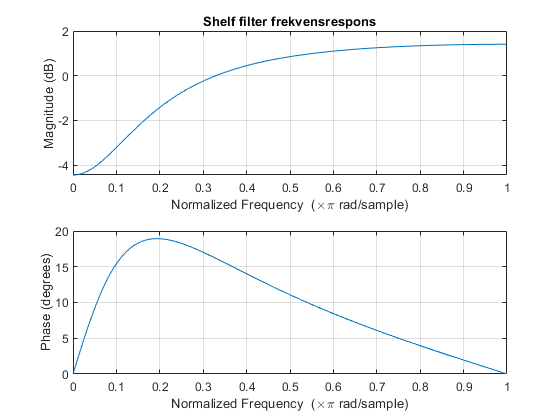


% Output c2d:
% H(z) = (z - 0.634)/(z - 0.3898)

%Bestemmelse af koefficienter fra output af c2d (skal ændres)
b = [1,-0.634];
a = [1,-0.3898];

% Tegn filter
freqz(b,a)
title('Shelf filter frekvensrespons');

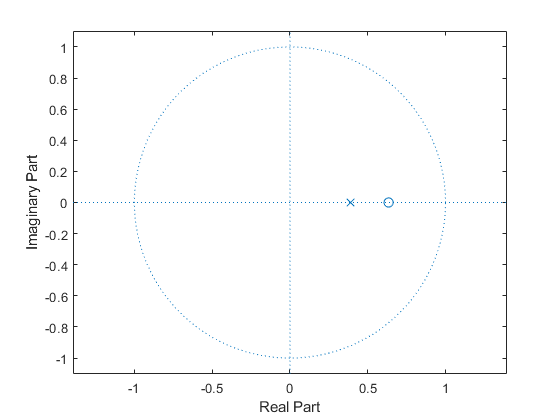


%Er H(z) filteret stabilt? Hvorfor / hvorfor ikke?
nulpunkter = roots([1,-0.634]);
poler = roots([1,-0.3898]);

zplane(nulpunkter, poler);

%Filtret er stabilt da alle poler er inden for enhedscirklen. Dvs. mellem
%-1 og 1.

%Find differensligningen der repræsenterer H(z), altså y(n) = ... 